Slow script, not very useful. Use `ikplot_demo` instead!

close all; clear;
p = stplat()

p =   stplat with properties:

             Br: 0.6000
             Pr: 0.8000
             Bk: [3×6 double]
             Pk: [3×6 double]
    Act_fixed_l: 0.6000
      Act_max_l: 0.9500
         Act_m1: 4.3800
         Act_m2: 0.4800
         Act_l1: 0.1105
         Act_l2: 0.6000
       Act_Inn1: 0.0815
       Act_Inn2: 0.0039
         Plat_m: 100
         Plat_I: [3×3 double]
       Plat_COM: [3×1 double]
       home_pos: [6×1 double]


hold on; view(3);
grid on;

Slider control

x=-10

x = -10

y=780

y = 780

z=-20

z = -20

phi=   -0.1

phi = -0.1000

theta= -0.03

theta = -0.0300

psi=   0.02

psi = 0.0200

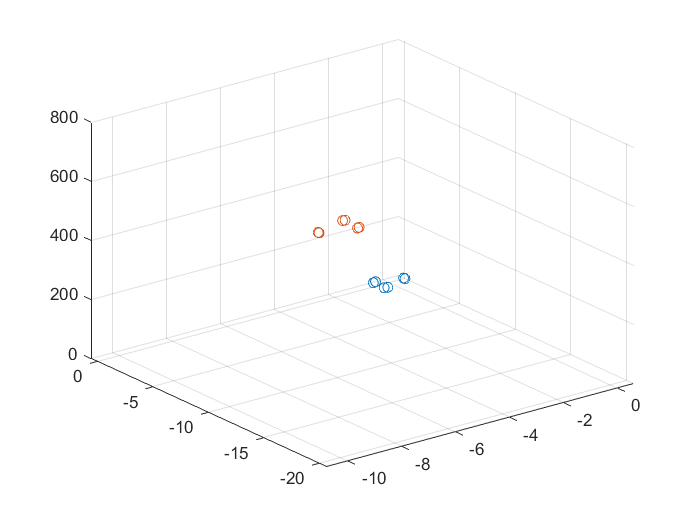


q = [x y z phi theta-pi/2 psi]';
%[l n a_w L] = p.ikine(q)
plot_platform(p, q)

function plot_platform(p, q)
    % Get IK positions and rotation matrix
    [~, ~, a_w, ~] = p.ikine(q);
    % Base points
    plot3(p.Bk(1,:), p.Bk(3,:), p.Bk(2,:), "O")
    % Top points
    plot3(a_w(1,:), a_w(3,:), a_w(2,:), "O");
end